% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc;
format long;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 11;
avgNum = 15;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-07-22/";

% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

file_name = "Blood_Plasma1(40x,495mW,Well3)_2500_24_2024-07-22-17.40.55.050.csv";
file_path = data_path+file_name;
blood_1_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,Well3)_2000_30_2024-07-22-17.42.38.167.csv";
file_path = strcat(data_path,file_name);
blood_2_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,Well3)_2000_30_2024-07-22-17.44.12.083.csv";
file_path = strcat(data_path,file_name);
blood_3_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,Well3)_2000_30_2024-07-22-17.45.47.837.csv";
file_path = strcat(data_path,file_name);
blood_4_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,Well3)_2000_30_2024-07-22-17.47.26.570.csv";
file_path = strcat(data_path,file_name);
blood_5_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,Well3)_2000_30_2024-07-22-17.49.02.207.csv";
file_path = strcat(data_path,file_name);
blood_6_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,Well3)_2000_30_2024-07-22-17.50.41.847.csv";
file_path = strcat(data_path,file_name);
blood_7_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,Well3)_2000_30_2024-07-22-17.52.32.197.csv";
file_path = strcat(data_path,file_name);
blood_8_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,Well3)_2000_30_2024-07-22-17.54.06.163.csv";
file_path = strcat(data_path,file_name);
blood_9_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,Well3)_2000_30_2024-07-22-17.55.53.260.csv";
file_path = strcat(data_path,file_name);
blood_10_3 = csvread(file_path, numMetadataRows, 0);

file_name = "NIST(40x,495mW)_50_100_2024-07-22-14.58.35.077.csv";
file_path = strcat(data_path,file_name);
NISTspectrum = csvread(file_path, numMetadataRows, 0);

file_name = "Polystyrene(40x,495mW)_60_100_2024-07-22-15.12.29.507.csv";
file_path = strcat(data_path,file_name);
poly1 = csvread(file_path, numMetadataRows, 0);
poly = mean(poly1(2:end,:));

file_name = "Silicon(40x,495mW)_50_100_2024-07-22-15.08.33.957.csv";
file_path = strcat(data_path,file_name);
Si1 = csvread(file_path, numMetadataRows, 0);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring and plotting unprocessed data

wavenumber = blood_1_3(1,:);

% trimming standard sample data to these WN's
t1 = 500;
t2 = 1800;
wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];
blood_1_3(:, blood_1_3(1, :) <= t1) = [];
blood_1_3(:, blood_1_3(1, :) >= t2) = [];
blood_2_3(:, blood_2_3(1, :) <= t1) = [];
blood_2_3(:, blood_2_3(1, :) >= t2) = [];
blood_3_3(:, blood_3_3(1, :) <= t1) = [];
blood_3_3(:, blood_3_3(1, :) >= t2) = [];
blood_4_3(:, blood_4_3(1, :) <= t1) = [];
blood_4_3(:, blood_4_3(1, :) >= t2) = [];
blood_5_3(:, blood_5_3(1, :) <= t1) = [];
blood_5_3(:, blood_5_3(1, :) >= t2) = [];
blood_6_3(:, blood_6_3(1, :) <= t1) = [];
blood_6_3(:, blood_6_3(1, :) >= t2) = [];
blood_7_3(:, blood_7_3(1, :) <= t1) = [];
blood_7_3(:, blood_7_3(1, :) >= t2) = [];
blood_8_3(:, blood_8_3(1, :) <= t1) = [];
blood_8_3(:, blood_8_3(1, :) >= t2) = [];
blood_9_3(:, blood_9_3(1, :) <= t1) = [];
blood_9_3(:, blood_9_3(1, :) >= t2) = [];
blood_10_3(:, blood_10_3(1, :) <= t1) = [];
blood_10_3(:, blood_10_3(1, :) >= t2) = [];

shifts = wavenumber;

blood1_3 = blood_1_3(2:end, :);
blood2_3 = blood_2_3(2:end, :);
blood3_3 = blood_3_3(2:end, :);
blood4_3 = blood_4_3(2:end, :);
blood5_3 = blood_5_3(2:end, :);
blood6_3 = blood_6_3(2:end, :);
blood7_3 = blood_7_3(2:end, :);
blood8_3 = blood_8_3(2:end, :);
blood9_3 = blood_9_3(2:end, :);
blood10_3 = blood_10_3(2:end, :);

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

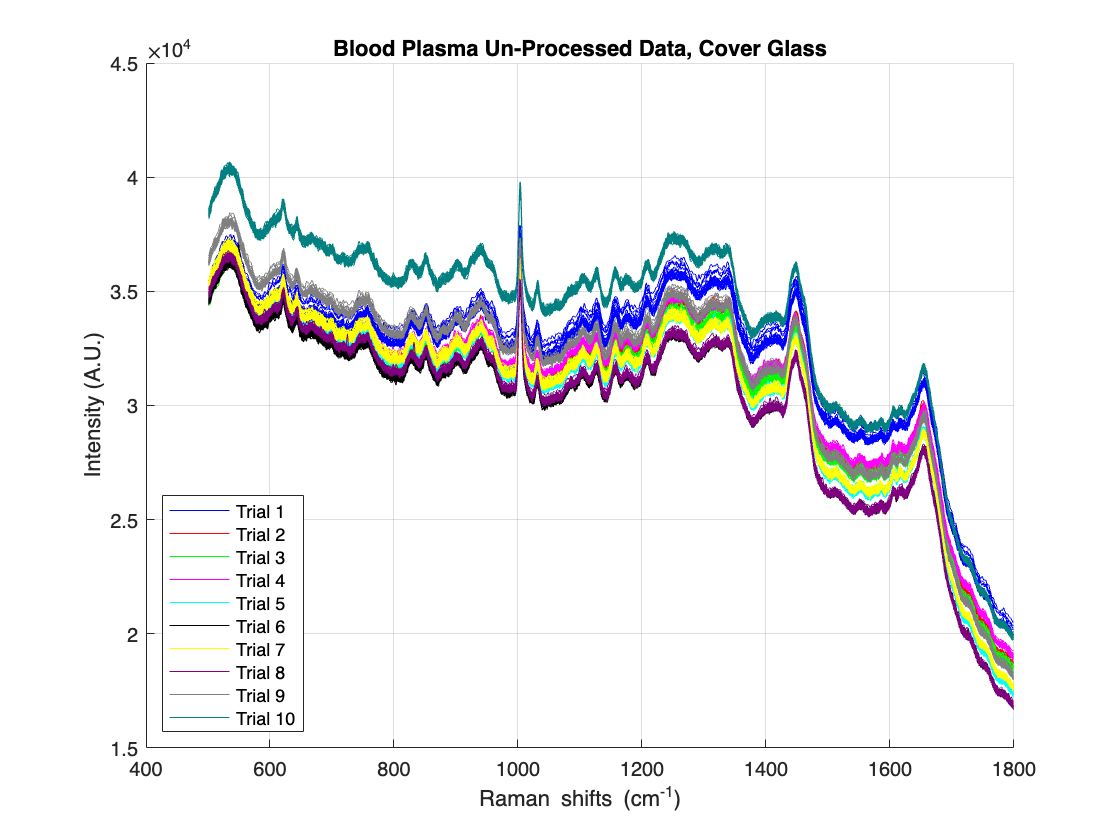

% Plotting unprocessed data

figure;
hold on;
grid on;
plot(wavenumber, blood1_3(1,:), 'Color', [0 0 1]); % Blue
plot(wavenumber, blood2_3(1,:), 'Color', [1 0 0]); % Red
plot(wavenumber, blood3_3(1,:), 'Color', [0 1 0]); % Green
plot(wavenumber, blood4_3(1,:), 'Color', [1 0 1]); % Magenta
plot(wavenumber, blood5_3(1,:), 'Color', [0 1 1]); % Cyan
plot(wavenumber, blood6_3(1,:), 'Color', [0 0 0]); % Black
plot(wavenumber, blood7_3(1,:), 'Color', [1 1 0]); % Yellow
plot(wavenumber, blood8_3(1,:), 'Color', [0.5 0 0.5]); % Purple
plot(wavenumber, blood9_3(1,:), 'Color', [0.5 0.5 0.5]); % Gray
plot(wavenumber, blood10_3(1,:), 'Color', [0 0.5 0.5]); % Teal
plot(wavenumber, blood1_3(2:end,:), 'Color', [0 0 1]); % Blue
plot(wavenumber, blood2_3(2:end,:), 'Color', [1 0 0]); % Red
plot(wavenumber, blood3_3(2:end,:), 'Color', [0 1 0]); % Green
plot(wavenumber, blood4_3(2:end,:), 'Color', [1 0 1]); % Magenta
plot(wavenumber, blood5_3(2:end,:), 'Color', [0 1 1]); % Cyan
plot(wavenumber, blood6_3(2:end,:), 'Color', [0 0 0]); % Black
plot(wavenumber, blood7_3(2:end,:), 'Color', [1 1 0]); % Yellow
plot(wavenumber, blood8_3(2:end,:), 'Color', [0.5 0 0.5]); % Purple
plot(wavenumber, blood9_3(2:end,:), 'Color', [0.5 0.5 0.5]); % Gray
plot(wavenumber, blood10_3(2:end,:), 'Color', [0 0.5 0.5]); % Teal
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Cover Glass');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'location', 'southwest');
hold off;

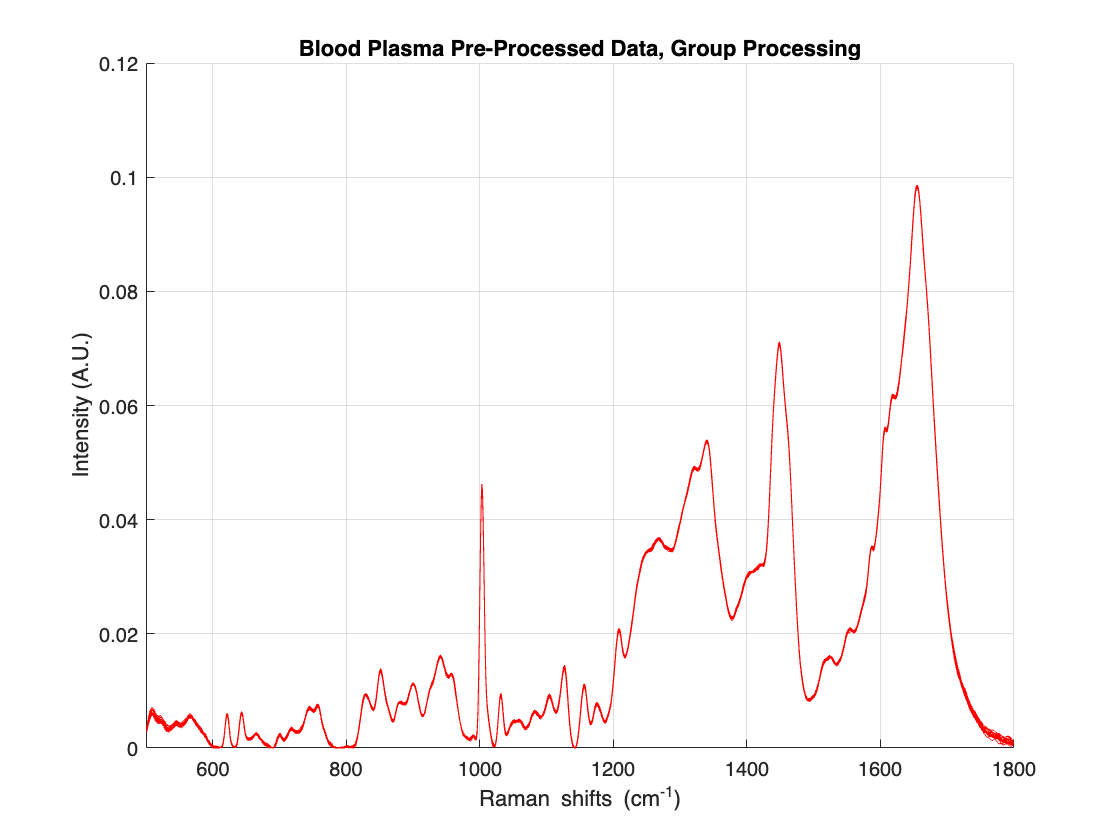

% Preprocessing the data

pro_blood1_3 = apply(blood1_3, [6,1,10,11,8,2,5,6,7]);
pro_blood2_3 = apply(blood2_3, [6,1,10,11,8,2,5,6,7]);
pro_blood3_3 = apply(blood3_3, [6,1,10,11,8,2,5,6,7]);
pro_blood4_3 = apply(blood4_3, [6,1,10,11,8,2,5,6,7]);
pro_blood5_3 = apply(blood5_3, [6,1,10,11,8,2,5,6,7]);
pro_blood6_3 = apply(blood6_3, [6,1,10,11,8,2,5,6,7]);
pro_blood7_3 = apply(blood7_3, [6,1,10,11,8,2,5,6,7]);
pro_blood8_3 = apply(blood8_3, [6,1,10,11,8,2,5,6,7]);
pro_blood9_3 = apply(blood9_3, [6,1,10,11,8,2,5,6,7]);
pro_blood10_3 = apply(blood10_3, [6,1,10,11,8,2,5,6,7]);

% Checking for processing full dataset at once vs individual

blood_3 = [blood1_3;blood2_3;blood3_3;blood4_3;blood5_3;blood6_3;blood7_3;blood8_3;blood9_3;blood10_3];
pro_blood_3 = apply(blood_3, [6,1,10,11,8,2,5,6,7]);

% Plotting pre-processed data

figure;
hold on;
grid on;
plot(wavenumber, pro_blood_3, '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, Group Processing');
xlim([500 1800]);
ylim([0 0.12]);
hold off;

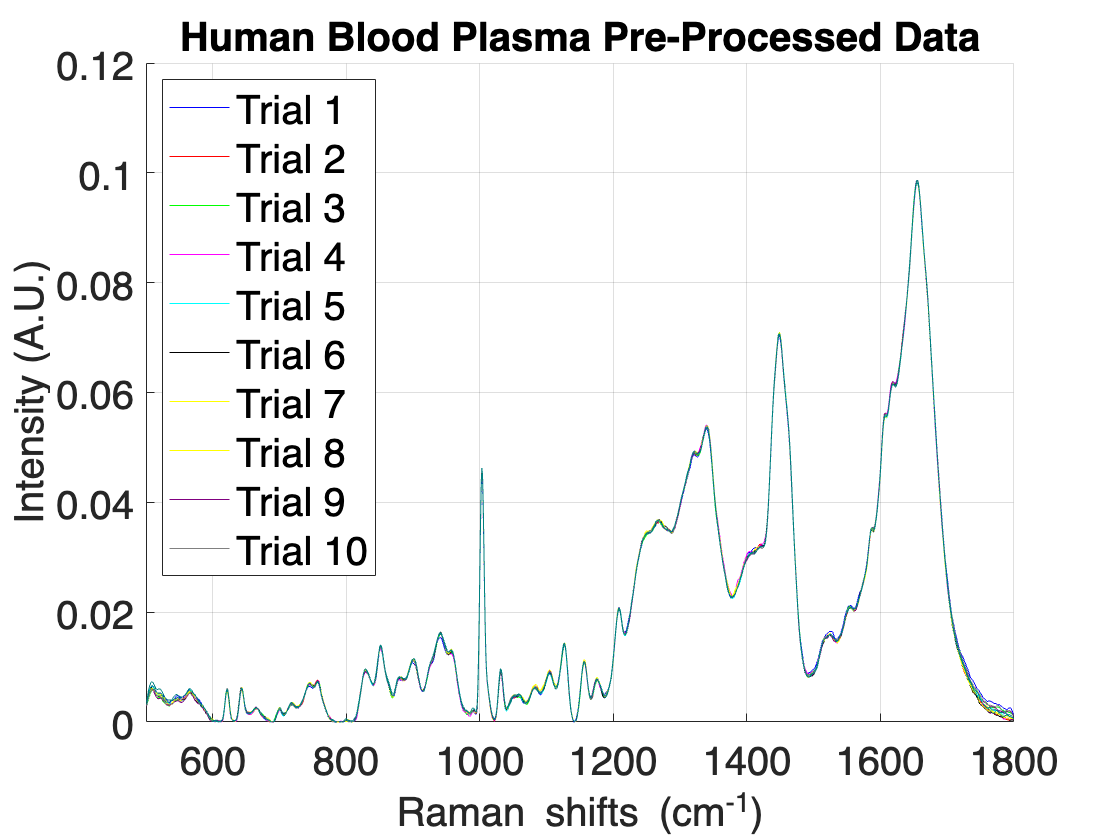

figure;
hold on;
grid on;
plot(wavenumber, pro_blood1_3, 'Color', [0 0 1]); % Blue
plot(wavenumber, pro_blood2_3, 'Color', [1 0 0]); % Red
plot(wavenumber, pro_blood3_3, 'Color', [0 1 0]); % Green
plot(wavenumber, pro_blood4_3, 'Color', [1 0 1]); % Magenta
plot(wavenumber, pro_blood5_3, 'Color', [0 1 1]); % Cyan
plot(wavenumber, pro_blood6_3, 'Color', [0 0 0]); % Black
plot(wavenumber, pro_blood7_3, 'Color', [1 1 0]); % Yellow
plot(wavenumber, pro_blood8_3, 'Color', [0.5 0 0.5]); % Purple
plot(wavenumber, pro_blood9_3, 'Color', [0.5 0.5 0.5]); % Gray
plot(wavenumber, pro_blood10_3, 'Color', [0 0.5 0.5]); % Teal
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Human Blood Plasma Pre-Processed Data');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'Location', 'northwest');
xlim([500 1800]);
ylim([0 0.12]);
fontsize(20,'points');
hold off;

function [t_val, p_val, df] = perform_ttest(av1, av2, std1, std2, n1, n2)
    t_val = (av1 - av2) / sqrt((std1^2 / n1) + (std2^2 / n2));
    df = ((std1^2 / n1) + (std2^2 / n2))^2 / ...
         (((std1^2 / n1)^2 / (n1 - 1)) + ((std2^2 / n2)^2 / (n2 - 1)));
    p_val = 2 * (1 - tcdf(abs(t_val), df));
end

function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end